# **Escuela CNS: Analisis de series de tiempo - Día 1**

**En esta primera parte de la actividad se leerá una hoja de datos con dos columnas: una correspondiente al tiempo y otra al voltaje normalizado de una señal ECG (electrocardiograma) proveniente de un paciente con fibrilación auricular paroxística. Los datos fueron obtenidos del repositorio público MIT-AFIB, utilizando la herramienta *****WaveForm DataBase Toolbox*****, que permite acceder de manera eficiente a estos registros directamente desde el código.**

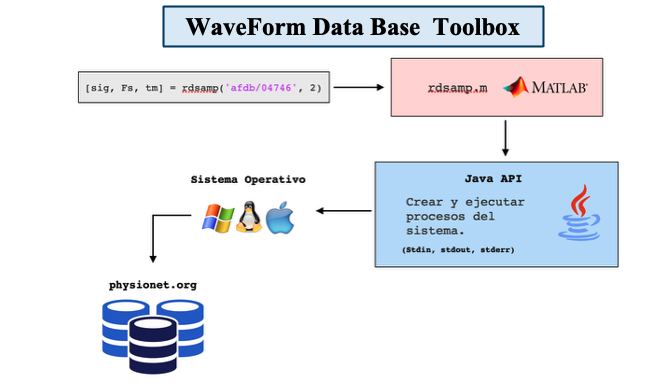

**Primeramente, se identificarán las principales características de estos mismos, como lo son el número de muestras y la frecuencia de muestreo con la cual fue digitalizada.**

% 1.- Leer datos desde el archivo .mat

load('px_actividad.mat')

% 2.- Crear los vectores que contienen a los tiempos y los valores

tiempo = data(:,1);

Unrecognized function or variable 'data'.

valor = data(:,2);

# **Sección #2**

**Una de las ventajas del repositorio MIT-AFIB es que los datos han sido validados por médicos especialistas, por lo que incluyen etiquetas que indican el inicio y el final de los episodios de fibrilación auricular. A continuación, se presentan los tiempos en los que estos episodios ocurren, en formato**** (hh:mm:ss.SSS).**

tiempo = seconds(tiempo); 

tiempo.Format = 'hh:mm:ss.SSS';


inicio_episodios = [
    duration("00:37:06.711"), 
    duration("00:47:44.443"), 
    duration("02:23:13.895"), 
    duration("03:19:55.153"), 
    duration("04:02:35.684"), 
    duration("04:37:11.904"), 
    duration("08:32:06.960")
];

fin_episodios = [
    duration("00:38:43.887"), 
    duration("00:48:16.300"), 
    duration("02:23:35.885"), 
    duration("03:20:12.715"), 
    duration("04:05:09.748"), 
    duration("04:37:31.979"), 
    duration("08:32:24.941")
];

periodo_sano = [duration("00:40:44.711"), duration("00:41:44.443")];

inicio_episodios_sec = seconds(inicio_episodios);
fin_episodios_sec = seconds(fin_episodios);

# **Sección #3**

## **Primera visualización del ECG      **

Se hará una primera visualización de los datos, así como la indicación mediante lineas verticales de donde comienzan y terminan los episodios.

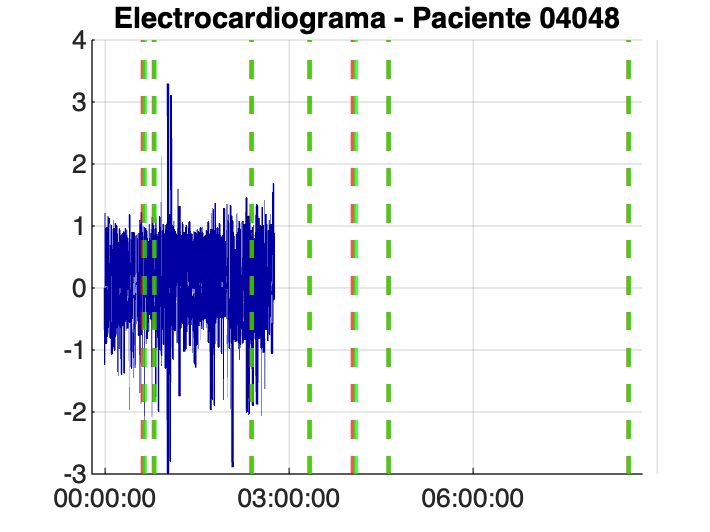

figure;
hold on;

% Agregar líneas verticales en los momentos especificados
for i = 1:length(inicio_episodios)
    xline(inicio_episodios(i), '--r', 'LineWidth', 1.6);
end

for i = 1:length(fin_episodios)
    xline(fin_episodios(i), '--g', 'LineWidth', 1.6);
end

% Agregar los XLIMS



plot(tiempo, valor, '-', 'LineWidth', 0.9, 'Color', '#0000A2'); % Señal original
title('Electrocardiograma - Paciente 04048')
grid on;

# **Sección #4**

## **Episodios de Fibrilación Auricular**

Para mejorar la visualización, es posible que el usuario elija entre cada uno de los siete episodios, para ver y analizar cada uno de estos por separado.

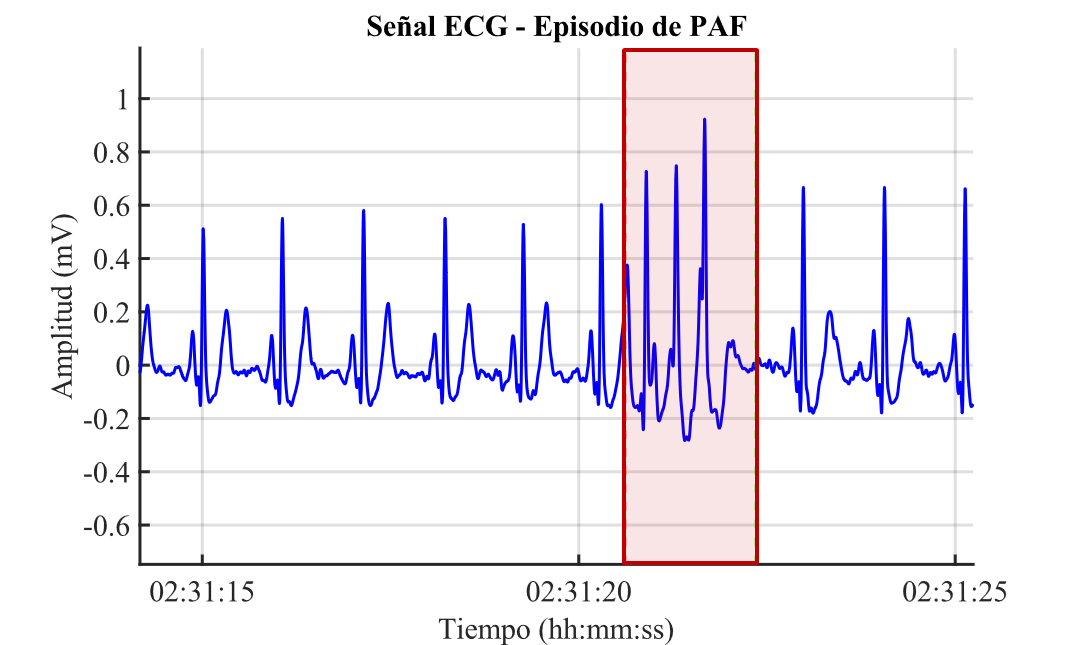

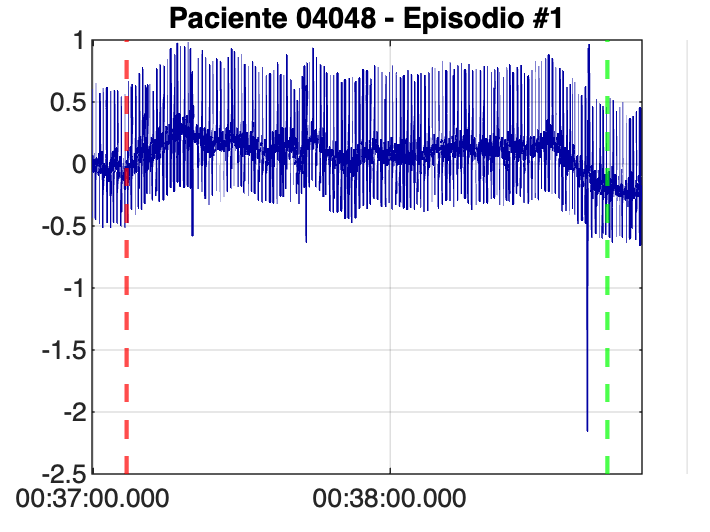

%Existen un total de siete episodios de PAF en toda la serie de tiempo

%Es posible elegir entre cada uno de estos episodios para visualizarlos por
%separado

episodio = 1; 

% ============================
% Margen de tiempo antes y después

margen = seconds(7);

figure;
plot(tiempo, valor, '-', 'LineWidth', 0.9, 'Color', '#0000A2'); 
hold on;

% lineas verticales de indicacion para episodios
for i = 1:length(inicio_episodios)
    xline(inicio_episodios(i), '--r', 'LineWidth', 1.6);
    xline(fin_episodios(i), '--g', 'LineWidth', 1.6);
end

%===============================================================================
% Zoom automático al episodio seleccionado con márgenes
if episodio >= 1 && episodio <= length(inicio_episodios)
    xlim([inicio_episodios(episodio) - margen, fin_episodios(episodio) + margen]);
else
    warning('Número de episodio invalido');
end
%===============================================================================

title(sprintf('Paciente 04048 - Episodio #%d', episodio));

grid on;

# **Sección #5**

## **Artefactos**

Los artefactos son generados debido a diversas situaciones, las cuales pueden introducir perturbaciones a la señal que dificultan el análisis. En esta sección se van a explorar algunos de ellos, con la intención de identificarlos y caracterizarlos.

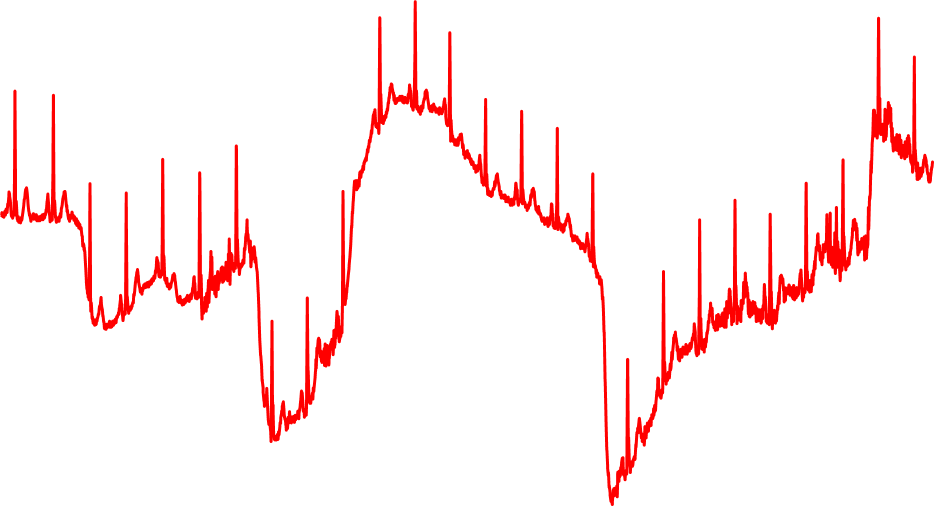                          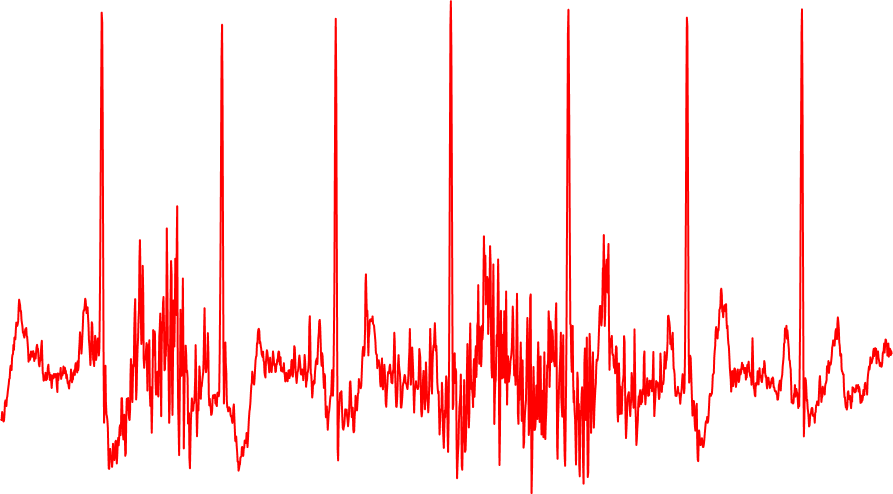

artefactos_inicio = [
    duration("01:43:44.711"), %Artefacto de movimiento
    duration("04:30:49.443"), %Miografia
    duration("05:59:39.895"), %Movimiento
    duration("00:20:00.000"), %Deriva

];

artefactos_fin = [
    duration("01:44:57.711"), 
    duration("04:30:59.443"), 
    duration("06:09:22.895"), 
    duration("00:25:00.000"),
];

**Existen un total de cuatro episodios definidos al principio de esta sección, pero no son los únicos. Estos se encuentran a lo largo de toda la serie de tiempo y unos son más severos que otros. **

**Por favor, visualiza cada uno de los cuatro episodios.**

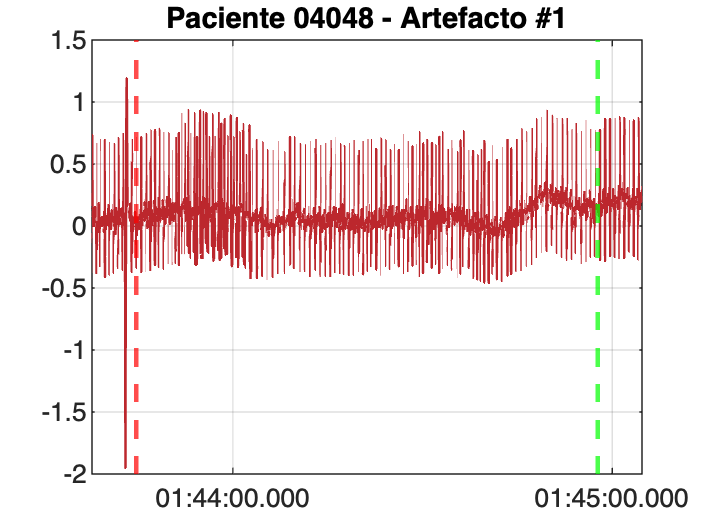

% Elegir el número de artefacto
%=============================
artefacto = 1; 
% ============================

figure;
plot(tiempo, valor, 'b-', 'LineWidth', 0.9, 'Color', '#bc272d'); 
hold on;


for i = 1:length(artefactos_inicio)
    xline(artefactos_inicio(i), '--r', 'LineWidth', 1.6);
    xline(artefactos_fin(i), '--g', 'LineWidth', 1.6);
end


if artefacto >= 1 && artefacto <= length(artefactos_inicio)
    xlim([artefactos_inicio(artefacto) - margen, artefactos_fin(artefacto) + margen]);
else
    warning('Número de episodio invalido');
end

title(sprintf('Paciente 04048 - Artefacto #%d', artefacto));

grid on;

# **Sección #6**

## **Filtrado avanzado**

A partir de este momento se optará por implementar una combinación de un filtro digital Butterworth de quinto orden y un algoritmo de promediado móvil. Con esto se busca reducir significativamente la deriva, al mismo tiempo que se atenúan las componentes de alta frecuencia.

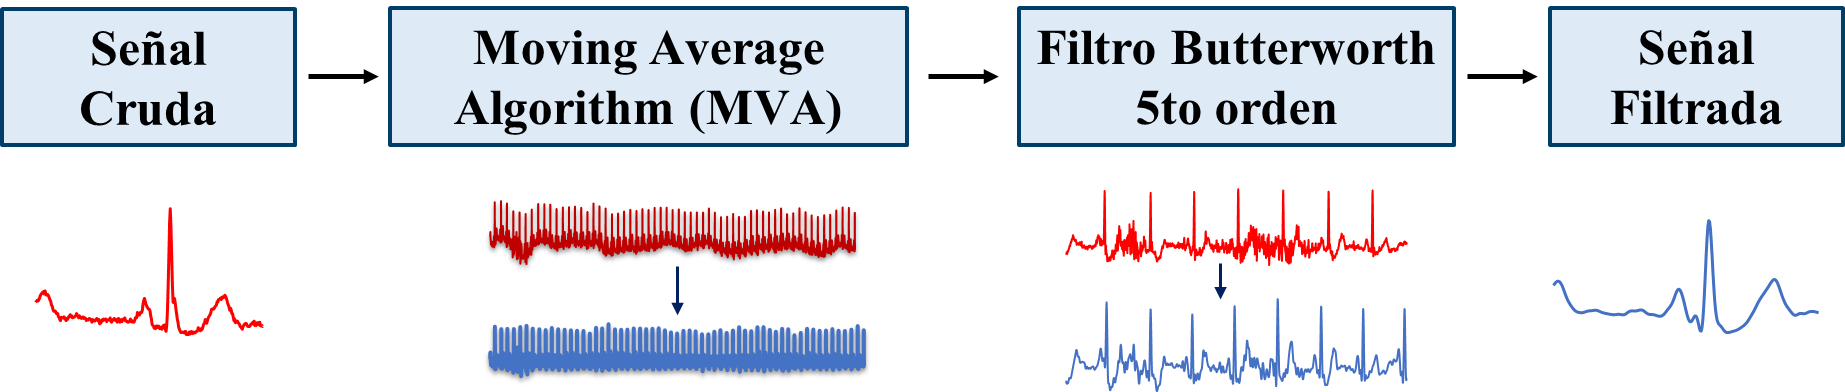

% === Filtro de media móvil + paso alto ===
window_size = 150;


valor_ma = movmean(valor, window_size);


pasa_altas = valor - valor_ma; 


% === Butterworth ===
%tiempo = double(tiempo);

tc = seconds(tiempo(2))-seconds(tiempo(1))

tc = 0.0040


f = 1/tc

f = 250


orden = 5;


fs = 250;
fc = 20; 


f_nyquist = fs/2;


fc = fc/f_nyquist;


[b5,a5] = butter(orden, fc, "low");


valor_filtrado = filtfilt(b5, a5, pasa_altas);



## Sección 6.1

**Ahora se hará una primera visualización de los filtros aplicados.**

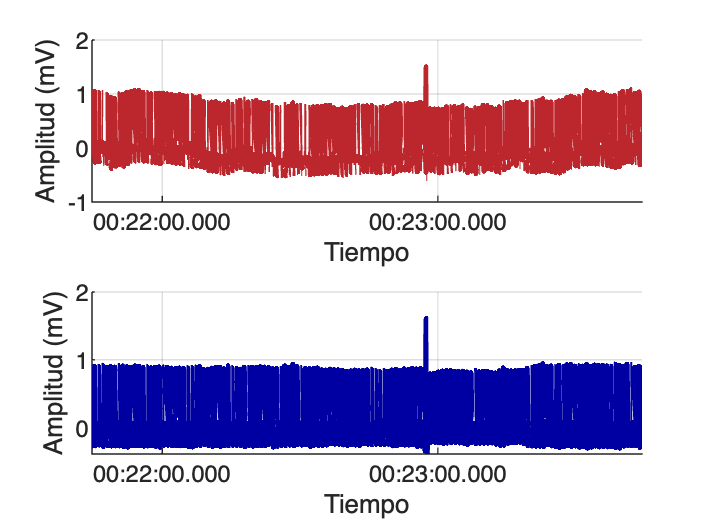


figure;

subplot(2,1,1);
hold on;

plot(tiempo, valor, 'LineWidth', 2, 'Color', '#BC272D');

xlabel('Tiempo');
ylabel('Amplitud (mV)');

xlim([periodo_sano(1) periodo_sano(2)]);

grid on;

subplot(2,1,2);
hold on;

plot(tiempo, valor_filtrado, 'LineWidth', 2, 'Color', '#0000A2');
xlabel('Tiempo');
ylabel('Amplitud (mV)');

xlim([periodo_sano(1) periodo_sano(2)]);

grid on;
linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');

# **Sección #7**

## **Medidas estadísticas básicas**

Es posible calcular métricas estadísticas que permitan caracterizar la señal desde un punto de vista cuantitativo. Con ello, se realizará una comparación de los resultados obtenidos para estas métricas en la señal cruda y en las dos etapas de filtrado aplicadas.

% === Estadísticas filtrado avanzado ===
media_valor = mean(valor);
desv_std_valor = std(valor);
max_valor = max(valor);
min_valor = min(valor);


media_avanzado = mean(valor_filtrado);
desv_std_avanzado = std(valor_filtrado);
max_avanzado = max(valor_filtrado);
min_avanzado = min(valor_filtrado);

etapas = {'Señal cruda'; 'Filtrado avanzado'};
medias = [media_valor; media_avanzado];
desvios = [desv_std_valor; desv_std_avanzado];
maximos = [max_valor; max_avanzado];
minimos = [min_valor; min_avanzado];

tabla_comparativa = table(medias, desvios, maximos, minimos, ...
    'RowNames', etapas, ...
    'VariableNames', {'Media_mV', 'Desv_std_mV', 'Max_mV', 'Min_mV'});

% Mostrar tabla
disp('Comparación de estadísticas entre las etapas:');
disp(tabla_comparativa);


# **Sección #8**

## **Visualización de la accion de los filtros**

**Una vez efectuado el proceso de filtrado, se hará una visualización para evaluar el efecto del filtro; primero en un par de ciclos de cardiacos y despues se vera como es que actuaron sobre los artefactos identificados**

ciclos = [duration("05:00:33.796"), duration("05:00:37.520")];

figure;
plot(tiempo, valor, '-', 'LineWidth', 1.2, 'Color', '#BC272D'); hold on;
plot(tiempo, valor_filtrado, '-', 'LineWidth', 1.2, 'Color', '#0000A2');
xlabel('Tiempo');
ylabel('Amplitud (mV)');
xlim([ciclos(1) ciclos(2)]);
title('ECG - Señal Original vs Filtrado Avanzado');
legend('Señal Original', 'Filtrado Avanzado');
grid on;

## Sección 8.1


% Como anteriormente se visualizó, existen un total de cuatro artefactos
% En esta sección podrán visualizar como es que los filtros actuaron para
% abatir estos mismos

% ============================
artefacto = 1; 
% ============================

margen = seconds(7)
figure;

hold on;
plot(tiempo, valor, '-', 'LineWidth', 0.9, 'Color', '#BC272D'); 
plot(tiempo, valor_filtrado, '-', 'LineWidth', 0.9, 'Color', '#0000A2');

% lineas verticales de indicacion para episodios
for i = 1:length(artefactos_inicio)
    xline(artefactos_inicio(i), 'k--', 'LineWidth', 1.6);
    xline(artefactos_fin(i), 'k--', 'LineWidth', 1.6);
end

% Zoom automático al episodio seleccionado con márgenes
if artefacto >= 1 && artefacto <= length(artefactos_inicio)
    xlim([artefactos_inicio(artefacto) - margen, artefactos_fin(artefacto) + margen]);
else
    warning('Número de episodio invalido');
end

title(sprintf('Paciente 04048 - Artefacto #%d', artefacto));

grid on;

## Ahora intenten replicar los conocimientos adquiridos con una nueva serie de tiempo. Pueden acceder al archivo llamado px_actividad.